**Entanglement networks: Or, with expository perspicacity.**

In which we examine the structure of the graphs built from many-body systems.

The (pure) state vector $|\Psi \rangle \;$of a composite system $U=A\cup B$ is an element of the tensor product $H=H_A \otimes H_B$ of the Hilbert spaces of the underlying systems. The density matrix $\rho_i =|\phi_i \rangle \langle \;\phi_i |$ of a (possibly irreducible) state $|\phi_i \rangle \;$is a Hermitian element of the Banach space over $H_i$. If $\rho \;$is the density matrix of a composite system, then define the *reduced density matrix *of subsystem $j$ by 


$$\begin{array}{l}
\rho_j =\mathrm{Tr}{\;}_{\bar{\left\lbrace j\right\rbrace } } \left(\rho \;\right)\\
\;\;\;\;\;=\sum_{i_1 ,i_2 \cdots i_N } |i_1 i_2 \cdots i_{j-1} i_{j+1} \cdots i_N \rangle \;\rho \langle \;i_1 i_2 \cdots {i_{j-1} i_{j+1} \cdots \;i}_N |\;
\end{array}$$


i.e. by contracting over all basis vectors generated by the tensor products of all subsystems other than $j$. 

For a state $\rho \;$define the von Neumann entropy $S=-\mathrm{Tr}\left(\rho \;\mathrm{log}\;\rho \;\right)$, taking the logarithm to the base of preference. The von Neumann entropy is basis-invariant, and is 0 iff $\rho \;$is a pure state. 

For a pure composite state $\rho \;$, the von Neumann entropy of the reduced density matrix of any subsystem is zero iff the subsystem is not entangled with any other subsystem.

If two systems are entangled, then measurement of one provides (possibly incomplete) information about the state of the other. The outcomes are correlated, and so the entropy of the composite system is less than the sum of the entropies of the subsystems in isolation - the entropy is sub-additive.

To quantify this, define the quantum mutual information $I=S\left(A\;\right)+S\left(B\right)-S\left(A\cup B\right)\ldotp \;$The QMI is zero iff the composite state is separable. Let's look at some examples. 

% Mutual information in product states
psi1 = [1 0];
psi2 = [1 -1j]/sqrt(2);
rho1 = conj(psi1)'.*psi1;
rho2 = conj(psi2').*psi2;
rho = kron(rho1,rho2) %Defining a product state

rho =    0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.5000i  -0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


QMI_prod = Entropy(rho1) + Entropy(rho2) - Entropy(rho)

QMI_prod = 0

% Mutual information in a Bell triplet
phi_plus = [1 0 0 1]/sqrt(2);
rho_plus = conj(phi_plus').*phi_plus;
rho_sub1 = PartialTrace(rho_plus,2);
rho_sub2 = PartialTrace(rho_plus,1);
QMI_ent = Entropy(rho_sub1) + Entropy(rho_sub2) - Entropy(rho_plus)

QMI_ent = 2.0000

% What about if the entanglement is not evenly distributed?
% Consider the state 000+001+111 (first two are fully entangled, third is weakly entangled
psi_i = normalize([1 1 0 0 0 0 0 1],'norm');
dims_i = [2 2 2];
rho_i = toDM(psi_i);
rho_i1 = PartialTrace(rho_i,[2 3],dims_i);
rho_i2 = PartialTrace(rho_i,[1 3],dims_i);
rho_i3 = PartialTrace(rho_i, [1 2], dims_i);
rho_i12  = PartialTrace(rho_i, 3, dims_i);
rho_i13 = PartialTrace(rho_i, 2, dims_i);
rho_i23 = PartialTrace(rho_i,1,dims_i);
QMI_12 = Entropy(rho_i1) + Entropy(rho_i2) - Entropy(rho_i12)

QMI_12 = 1.2865

QMI_13 = Entropy(rho_i1) + Entropy(rho_i3) - Entropy(rho_i13)

QMI_13 = 0.5500

QMI_23 = Entropy(rho_i2) + Entropy(rho_i3) - Entropy(rho_i23)

QMI_23 = 0.5500

%So we see that qubits 1 & 2 are more entangled than other pairs

% Let's look at a bigger system; a product of a free qubit and
% a Bell triplet
triplet = toDM([1 0 0 1]/sqrt(2)); %spins A and B
qbit = toDM([1 1]/sqrt(2)); %spin C
Phi = kron(triplet,qbit);
dims = [2 2 2] ;%for the PartialTrace calls
%Compute the mutual information between A and B vs A and C

redAB = PartialTrace(Phi, 3, dims);
redAC = PartialTrace(Phi, 2, dims);
redA = PartialTrace(Phi,[2 3],dims); %Equivalently, can trace B out of redAB
redB = PartialTrace(Phi,[1 3],dims);
redC = PartialTrace(Phi,[1 2],dims);
QMI_AB = Entropy(redA) + Entropy(redB) - Entropy(redAB)

QMI_AB = 2

QMI_AC = Entropy(redA) + Entropy(redC) - Entropy(redAC)

QMI_AC = -6.6613e-16

Unfortunately, the QMI does not uniquely determine states. However, it *does*  provide information about the correlations between subsystems. Exactly what equivalence this imposes between states remains to be determined (at least, by me). Perhaps there is an equivalence up to local unitary transformations... Ah: In some conditions. See van den nest 2005. See also Cluster states...

**Graph states**

Traditionally, a *Graph state* is a state specified by the structure of a graph as follows: 

- Prepare the state $|+\rangle {\;}^{\otimes N}$, where N is the number of graph nodes

- For each edge $e_{\mathrm{ij}}$, if $e_{\mathrm{ij}} =1$ apply $\mathrm{CZ}\left(i,j\right)$.

- More information [https://en.wikipedia.org/wiki/Graph_state](https://en.wikipedia.org/wiki/Graph_state) 

Here, we reverse this construction. For a composite state $\rho$ define the weights of the graph $\Gamma \;$by $\Gamma_{\mathrm{ij}\;} =\mathrm{QMI}\left(i,j\right)$ for each pair of irreducible subsystems $i,j\ldotp$

Let's look at the graphs for the states above.

tolerance = 1e-6;
%Kill off any edges that accidentally appear
%due to limited numerical precision
Gamma_prod = dm_to_adj(rho, tolerance);

Undefined function or variable 'dm_to_adj'.

Gamma_trip = dm_to_adj(rho_plus,tolerance);
Gamma_inc = dm_to_adj(rho_i,tolerance);
Gamma_3body = dm_to_adj(Phi,tolerance)
%dm_to_graph returns the Laplacian, which we'll get to later

figure()
subplot(2,2,1)
plot(graph(Gamma_prod))
title('Graph of product state')
subplot(2,2,2)
plot(graph(Gamma_trip))
title('Graph of triplet state')
subplot(2,2,3)
plot(graph(Gamma_3body))
title('Graph of triplet*qubit')
subplot(2,2,4)
g_inc = graph(Gamma_inc);
LW = 4*g_inc.Edges.Weight;
plot(g_inc,'LineWidth',LW)
title('Incommensurate entanglement')

**Graph Laplacian**

The Laplacian matrix of a graph $G$ is defined by $L_G =D-A$, where $D$ is a diagonal matrix whose entries are the degree of the corresponding node (sum of all weights of edges connected to that node) and $A$is the adjacency matrix, whose entries $A_{\mathrm{ij}}$ are the weights between the nodes $i,j$. 

Ah: This is where the cluster state definition arises. The cluster state will allow for negative weights as the edges are defined by the *correlators*. Actually - they don't quite seem to do the trick either, or I don't understand their structure (or both). Further work!

(There is also a normalized Laplacian, but it shares most (if not all?) properties). Some useful properties:

- $L_G$ is positive semidefinite, and therefore has positive definite eigenvalues.

- $L_G \;$is symmetric, and therefore its eigenvectors are orthogonal.

- The dimension of the nullspace of $L_G$ is the number of connected components of $G$.

- The second-smallest eigenvalue of $L_G$ is called the Fielder eigenvalue, and it is nonzero iff the graph is connected. The Fielder eigenvector is used to estimate sparse cuts of graphs.

- The nullspace of $L_G$ is spanned by multiples of the vector of ones?

Let's look at the Laplacians for the states above.

The first graph is disconnected, and so its Laplacian is trivially all zeros. There are no connected components, so no nonzero eigenvalues. Equivalently, there are two disjoint (trivial) subgraphs, and so there are two zero eigenvalues. 

For the second graph;

[vec_trip, val_trip] = eigs(Gamma_trip)

The graph is connected. The eigenvectors correspond to the odd and even modes of the graph.

For the qubit and triplet product:

[vec_3body, val_3body] = eigs(Gamma_3body)

There are two disjoint graphs, so one eigenvalue is zero. The corresponding eigenvector spans only the subspace of that node. The subspace corresponding to the other nodes shows the same structure as the triplet. This reveals another property: The eigenvalues of the disjoint union of two graphs G and H on N and m nodes are $e_{\mathrm{g1}} ,e_{\mathrm{g2}} ,\ldotp \ldotp \ldotp e_{g_N } ,e_{\mathrm{h1}} ,\ldotp \ldotp \ldotp e_{\mathrm{hM}}$ , the eigenvectors are $v_{g_1 } \oplus 0,\ldotp \ldotp \ldotp 0\otimes v_{\mathrm{h1}} ,\ldotp \ldotp \ldotp 0\otimes v_{\mathrm{hM}}$, and the Laplacian has a block diagonal form. Open question: What is the physical interpretation of the function $\sum_i \;e_i \overrightarrow{{\left\lbrace v\right\rbrace }_i }$?

[vec_inc, val_inc] = eigs(Gamma_inc)
sum(vec_inc*val_inc)

**Nonlocal volume**

Motivated by noticing

$H\left(X\right)+H\left(Y\right)=H\left(\rho_x \otimes \rho_Y \right)=H\left(\lambda \;\right)$ we have


$$\begin{array}{l}
I\left(X,Y\right)=H\left(\rho_x \otimes \rho_Y \right)-H\left(\rho_{\left.\mathrm{XY}\right)} \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=H\left(\lambda \right)-H\left(\rho \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\mathrm{Tr}\left(\lambda \;\mathrm{log}\;\lambda -\rho \;\mathrm{log}\;\rho \;\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\mathrm{Tr}\;\left(\eta \;\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\eta :=\rho \;\mathrm{log}\;\rho -\lambda \;\mathrm{log}\;\lambda 
\end{array}$$


And we may also seek a (Hermitian at least) factorization


$$\eta =\Omega^{\dagger \;} \Omega \;\mathrm{so}\;I\left(X,Y\right)=\langle \;\Omega ,\Omega \;\rangle =||\Omega \;||\;$$


So let's cook up some examples.

A Bell triplet;


$$\Psi =\sum_i {|\mathrm{ii}\rangle \langle \;\mathrm{ii}|}$$


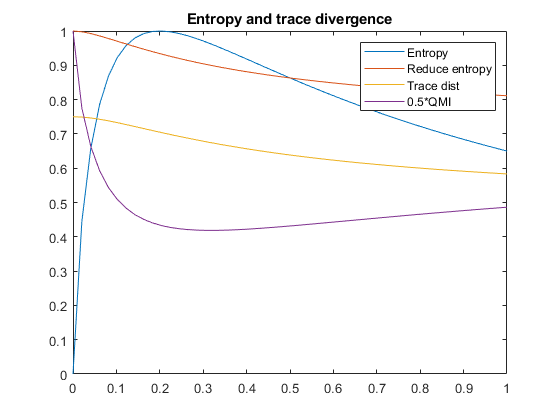

P = linspace(0,1,50);
Ent = zeros(size(P));
Trc = zeros(size(P));
Had = [1 1 ;1 -1]/sqrt(2);
Had2 = kron(Had, Had);
Y2 = kron(Pauli('Y'),Pauli('Y'));
for i=1:length(P)
    p = P(i);
    psi  = [0 1 2 0]';
    phi = [1 0 0 -1i]';
    psi = Y2*psi;
    phi = Y2*phi;
    rho = p*toDM(psi) + 0.2*toDM(phi);
    rho = rho/trace(rho);
    rhoA = TrX(rho,2,[2 2]);
    rhoB = TrX(rho,1,[2 2]);
    lambda = kron(rhoA,rhoB);
    Trc(i) = 1-trace(rho'*lambda);
    Ent(i) = Entropy(rho);
    R_ent(i) = Entropy(rhoA);
end
figure()
plot(P,Ent)
hold on
plot(P,R_ent)
plot(P,Trc)
plot(P,R_ent-0.5*Ent)
legend('Entropy','Reduce entropy','Trace dist','0.5*QMI')
title('Entropy and trace divergence')
hold off
ylim([0,1])

% Indeed, in this example, conjugating rhoA by PauliY gives a different curve.
% Therefore perhaps this trace distance is best used as a defn of an optimum
% Wait - one should compare all bases on equal footing, no? Best exmined further on paper I think


It is convenient to express these in their eigenbasis, as

$H\left(\rho \right)=\sum_i p_i \mathrm{log}\left(p_i \right)$ is a sum over diagonal elements

But of course logm is not a group homomorphism (ie log(AB) is not log(A) + log(B) - but it is when A and B commute!)

The zero eigenvalues of rho prevent the matrix log. What about:

[ur,vr] = eigs(rho);
